# LAB 4 - Zak Steenhoek - MAT 275

# Exercise 1

clc; clear;

### **Part (a)**

type 'LAB04ex1.m'

function results = LAB04ex1
    t0 = 0; tf = 40; y0 = [1;0];
    [t,Y] = ode45(@f,[t0,tf],y0,[]);
    y = Y(:,1); v = Y(:,2);    % y in output has 2 columns corresponding to u1 and u2


    figure(1); clf; tiledlayout(1,2);
    % Left plot
    ax1=nexttile; grid on; hold on;
    plot(ax1,t,y); plot(ax1,t,v); hold off;
    legend(ax1, 'y(t)', 'v(t)');
    xlabel(ax1,'t'); ylabel(ax1, 'y, v(t)=y''(t)'); 
    ylim([-3.8,3.8]);
    % Right plot
    ax2 = nexttile;
    plot(ax2, y,v); grid on;
    xlabel(ax2, 'y'); ylabel(ax2, 'v(t)=y''(t)');
    ylim([-3.8,3.8]); xlim([-3,3]);
        
    results = [t, Y(:,1), Y(:,2)];

end
 %----------------------------------------------------------------------
function dydt = f(t,Y)
    y=Y(1); v=Y(2);
    dydt = [v; 5*sin(t)-4*v-2*y];
end


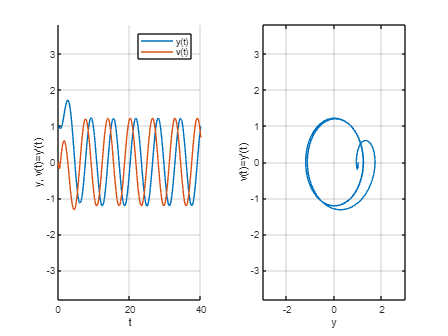

results = LAB04ex1;

### **Part (b)**

zc = diff(sign(results(:,3))); % finds difference in signs of derivitive values. If difference occurs, sign change has occured. 
                               % If sign change occurs && is negative (diff(pos-->neg) will be neg; (1-(-1))=-2); local max has occured.
idxZC = find(zc < 0)+1;        % find index of maxima. Graphical analysis not shown here showed that index+1, compared to just index, was closest to real value.
iMaximas = idxZC(end-2:end);   % isolate last 3 maximas
last3Maxima = results(iMaximas,:);
fprintf('Last 3 Maxima are:\n'); last3Maxima

Last 3 Maxima are:


last3Maxima =    21.7879    1.2116   -0.0505
   28.0710    1.2116   -0.0505
   34.3542    1.2116   -0.0505


### Part (c)

The long term behavior of Y is that it falls into step behind v and stays there indefinitley, as shown by the phase graph overlapping nearly perfectly with the exception of the very beginning.

### **Part (d)**

type LAB04ex1d

function LAB04ex1d
    t0 = 0; tf = 40; y0 = [1.5;-1.4];
    [t,Y] = ode45(@f,[t0,tf],y0,[]);
    y = Y(:,1); v = Y(:,2);    % y in output has 2 columns corresponding to u1 and u2

    figure(2); clf; tiledlayout(1,2);
    % Left plot
    ax1=nexttile; grid on; hold on;
    plot(ax1,t,y); plot(ax1,t,v); hold off;
    legend(ax1, 'y(t)', 'v(t)');
    xlabel(ax1,'t'); ylabel(ax1, 'y, v(t)=y''(t)'); 
    ylim([-3.8,3.8]);
    % Right plot
    ax2 = nexttile;
    plot(ax2, y,v); grid on;
    xlabel(ax2, 'y'); ylabel(ax2, 'v(t)=y''(t)');
    ylim([-3.8,3.8]); xlim([-3,3]);


end
 %----------------------------------------------------------------------
function dydt = f(t,Y)
    y=Y(1); v=Y(2);
    dydt = [v; 5*sin(t)-4*v-2*y];
end


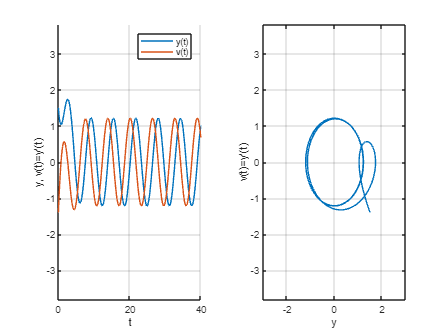

LAB04ex1d

The long term behavior of y does not change at all from the previous problem. while in the beginning the graphs are off phase, toward infinity, this graph overlaps itself indefinitely.

# Exercise 2

**Read the instructions in your lab pdf file carefully!**

### Part (a)

Create a new M-file with the differential equation changed

type  LAB04ex2

function LAB04ex2
    t0 = 0; tf = 40; y0 = [1;0];
    [t,Y] = ode45(@f,[t0,tf],y0,[]);
    y = Y(:,1); v = Y(:,2);    % y in output has 2 columns corresponding to u1 and u2


    figure(3); clf; tiledlayout(1,2);
    % Left plot
    ax1=nexttile; grid on; hold on;
    plot(ax1,t,y); plot(ax1,t,v); hold off;
    legend(ax1, 'y(t)', 'v(t)');
    xlabel(ax1,'t'); ylabel(ax1, 'y, v(t)=y''(t)'); 
    ylim([-3.8,3.8]);
    % Right plot
    ax2 = nexttile;
    plot(ax2, y,v); grid on;
    xlabel(ax2, 'y'); ylabel(ax2, 'v(t)=y''(t)');
    ylim([-3.8,3.8]); xlim([-3,3]);
end
 %----------------------------------------------------------------------
function dydt = f(t,Y)
    y=Y(1); v=Y(2);
    dydt = [v; 5*sin(t)-4*y.^2*v-2*y];
end


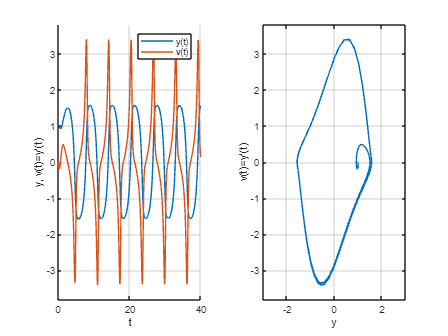

LAB04ex2

### Part (b)

It seems that the beginning phase disruption between y and v is shorter in figure 8 than figure 7. 

### Part (c)

the long term behavior of both problems is similar; they both fall into step with eachother and the difference in phase levels out. In problem 7, the amplitude of y is marginally greater than that in problem 4. The amplitude of the graphs of v, however, if much greater in problem 7. This means that the change in slope in problem 7 is greater than that in problem 4.

### Part (d)

You will have to create another M-file, LAB04ex2d.

type LAB04ex2d

function LAB04ex2d
    t0 = 0; tf = 40; y0 = [1;0];
    [t,Y] = ode45(@f,[t0,tf],y0,[]);
    y = Y(:,1); %v = Y(:,2);    % y in output has 2 columns corresponding to u1 and u2

    [te, Ye] = euler(@f,[t0,tf],y0,400);
    ye = Ye(:,1);

    figure(4); clf;
    grid on; hold on;
    plot(t,y,'Color','black'); plot(te,ye,'Color','red'); hold off;
    legend('ode45', 'euler');
    xlabel('t'); ylabel('y'); 
    ylim([-3.8,3.8]);
end
 %----------------------------------------------------------------------
function dydt = f(t,Y)
    y=Y(1); v=Y(2);
    dydt = [v; 5*sin(t)-4*y.^2*v-2*y];
end


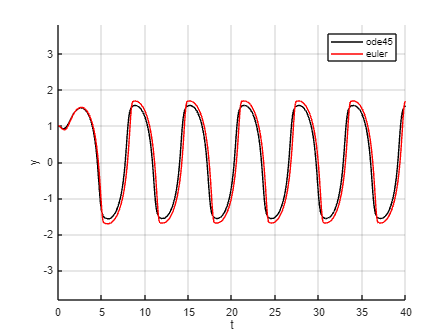

LAB04ex2d

The solutions are not quite identical, the ulers approximation has a warped shape near the graph maxima and mimima. If you increased the step size to, say 4000, it would look visually identical at this zoom to the ode45 solution.

# Exercise 3

type LAB04ex3

function LAB04ex3
    t0 = 0; tf = 40; y0 = [1;0];
    [t,Y] = ode45(@f,[t0,tf],y0,[]);
    y = Y(:,1); v = Y(:,2);    % y in output has 2 columns corresponding to u1 and u2


    figure(5); clf; tiledlayout(1,2);
    % Left plot
    ax1=nexttile; grid on; hold on;
    plot(ax1,t,y); plot(ax1,t,v); hold off;
    legend(ax1, 'y(t)', 'v(t)');
    xlabel(ax1,'t'); ylabel(ax1, 'y, v(t)=y''(t)'); 
    ylim([-3.8,3.8]);
    % Right plot
    ax2 = nexttile;
    plot(ax2, y,v); grid on;
    xlabel(ax2, 'y'); ylabel(ax2, 'v(t)=y''(t)');
    ylim([-3.8,3.8]); xlim([-3,3]);
end
 %----------------------------------------------------------------------
function dydt = f(t,Y)
    y=Y(1); v=Y(2);
    dydt = [v; 5*sin(t)-4*y*v-2*y];
end


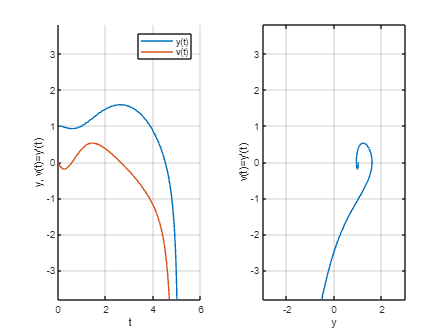

LAB04ex3

This behavior is significantly different than that in problem 7. The graph of y trends toward -infinity, so the graph of v does as well. MATLAB throws a warning message that it cannot integrate without reducing the step size below the numerical minimum, indicating that y(t) has gone nearly vertical.

# Exercise 4

type LAB04ex4

function LAB04ex4
    t0 = 0; tf = 40; y0 = [1;0;0.5];
    [t,Y] = ode45(@f,[t0,tf],y0,[]);
    y = Y(:,1); v = Y(:,2); w = Y(:,3);   % y in output has 2 columns corresponding to u1 and u2


    figure(3); clf; tiledlayout(1,2);
    % Left plot
    ax1=nexttile; grid on; hold on;
    plot(ax1,t,y,'Color','blue'); plot(ax1,t,v,'Color','red'); plot(ax1,t,w,'Color','black'); hold off;
    legend(ax1, 'y(t)', 'v(t)', 'w(t)');
    xlabel(ax1,'t'); ylabel(ax1, 'y, v(t)=y''(t)'); 
    ylim([-3.8,3.8]);
    % Right plot
    ax2 = nexttile;
    plot3(ax2, y,v,w); grid on; hold on; view([-40,60]);
    xlabel(ax2, 'y'); ylabel(ax2,'v=y'''); zlabel(ax2,'w=y'''''); 
    ylim([-3.8,3.8]); xlim([-3,3]);
end
 %----------------------------------------------------------------------
function dydt = f(t,Y)
    y=Y(1); v=Y(2); w=Y(3);
    dydt = [v; w; 5*cos(t)-4*y.^2*w-8*y*v.^2-2*v];
end


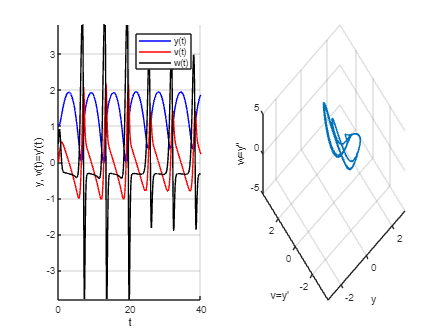

LAB04ex4